% OPTI 512L
% LAB 1
% Mohanbabu Mani

% 1. (a)

n = 10;
v1 = zeros(1,n);
for k = 1:n
    v1(k) = (k-1) * (30/(n-1)); 
end
v2 = 0 : (30/(n-1)) : 30;
v3 = linspace(0, 30, n);
v1, v2, v3

v1 =          0    3.3333    6.6667   10.0000   13.3333   16.6667   20.0000   23.3333   26.6667   30.0000


v2 =          0    3.3333    6.6667   10.0000   13.3333   16.6667   20.0000   23.3333   26.6667   30.0000


v3 =          0    3.3333    6.6667   10.0000   13.3333   16.6667   20.0000   23.3333   26.6667   30.0000



% 1. (b)

% 0:30/10:30 is 30/10=3 giving 11 values 0:3:30
% linspace (0,30,10) gives 10. So, make linspace to output 11 values

X = 0:30/10:30;       
Y = linspace(0, 30, 11);  
X,Y

X =      0     3     6     9    12    15    18    21    24    27    30


Y =      0     3     6     9    12    15    18    21    24    27    30



% 1. (c)

% r=0:0.3:2 adds 0.3 to 0 untill a number less than or equal to 2 is
% arrived

r=0:0.3:2

r =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000


% 2.

lengths =[10, 100, 1000, 10000];
counts = arrayfun(@(n)sum(abs(randn(n,1))>2), lengths);
fraction = counts ./ lengths;
prob = 2*(1-0.5*(1+erf(2/sqrt(2))));
expect = lengths * prob

expect =     0.4550    4.5500   45.5003  455.0026


tabulate = table(lengths.', counts.', fraction.', expect.', ...
    'VariableNames',{'N','ObservedCount','ObservedFraction','ExpectedCount'});
disp(tabulate)

      N      ObservedCount    ObservedFraction    ExpectedCount
    _____    _____________    ________________    _____________

       10           0                   0             0.455    
      100           2                0.02              4.55    
     1000          41               0.041              45.5    
    10000         456              0.0456               455    



fprintf('Probability P(|z|>2) = %.6f (=%.2f%%)\n', prob, 100*prob);

Probability P(|z|>2) = 0.045500 (=4.55%)


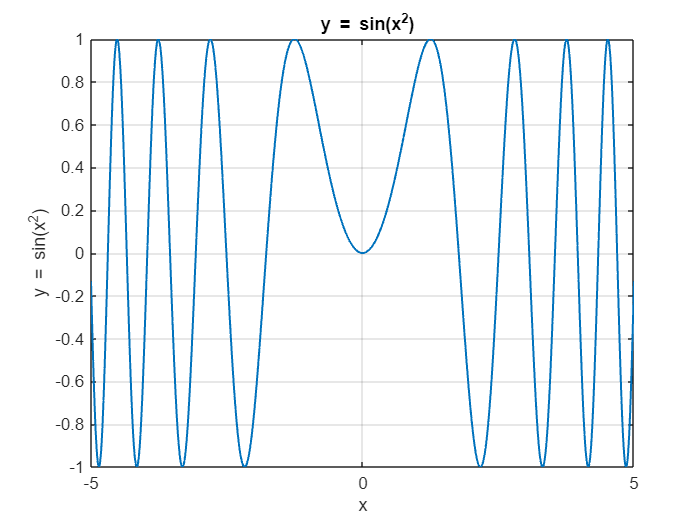

% 3. 

x = linspace(-5, 5, 1000); 
y = sin(x.^2); 
figure(1)
plot(x, y, 'LineWidth', 1.2)
grid on
xlabel('x')
ylabel('y = sin(x^2)')
title(' y = sin(x^2)')

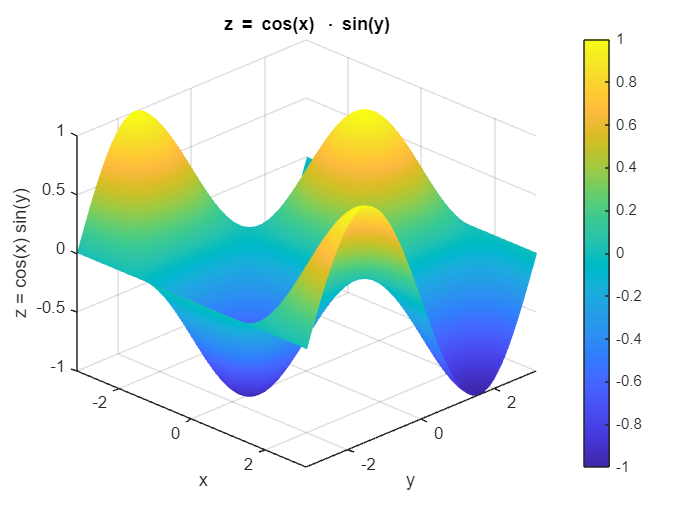



xr = linspace(-pi, pi, 121);
yr = linspace(-pi, pi, 121);
[X, Y] = meshgrid(xr, yr);
Z = cos(X) .* sin(Y);  
figure(2)
surf(X, Y, Z)
shading interp  
xlabel('x')
ylabel('y')
zlabel('z = cos(x) sin(y)')
title('z = cos(x) \cdot sin(y)')
colorbar
axis tight
view(45, 30)                     
grid on

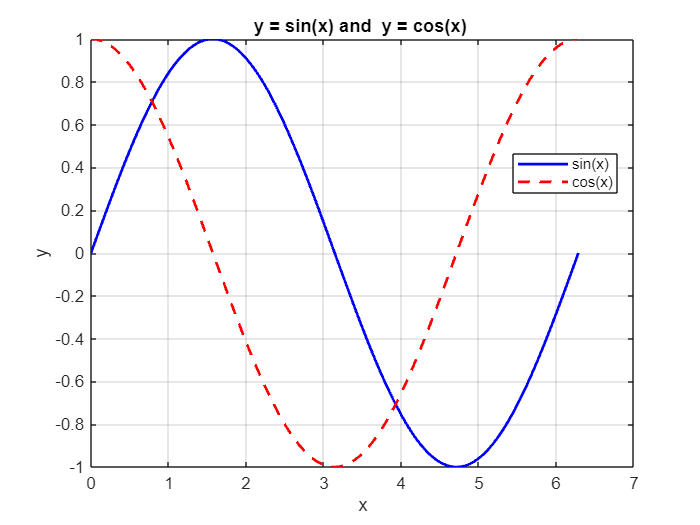


x2 = linspace(0, 2*pi, 500);
figure(3)
plot(x2, sin(x2), 'b-', 'LineWidth', 1.6)   
hold on
plot(x2, cos(x2), 'r--', 'LineWidth', 1.6) 
hold off
grid on
xlabel('x')
ylabel('y')
title('y = sin(x) and  y = cos(x) ')
legend('sin(x)', 'cos(x)', 'Location', 'best')

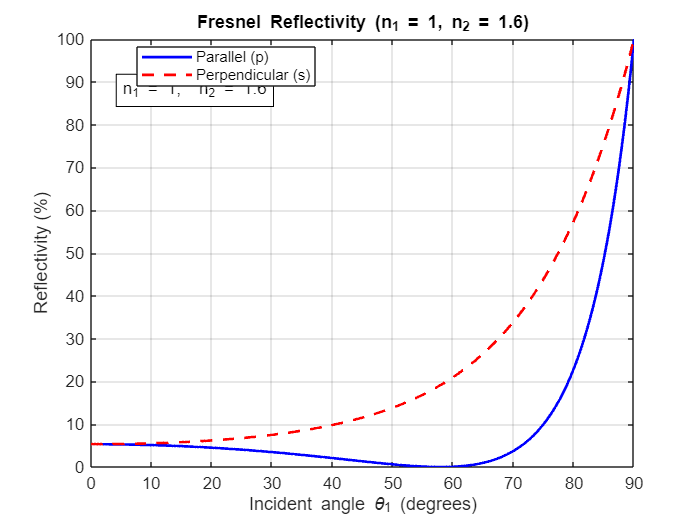

% 4.


n1 = 1.0;
n2 = 1.6;
theta1 = linspace(0,90,901);   
theta2 = asind( (n1./n2) .* sind(theta1) ); 

c1 = cosd(theta1);
c2 = cosd(theta2);

R_par  = ( ( n2.*c1 - c2 ) ./ ( c2 + n2.*c1 ) ).^2;        
R_perp = ( ( c1 - n2.*c2 ) ./ ( c1 + n2.*c2 ) ).^2;       

Rpar_pct  = 100 * R_par;
Rperp_pct = 100 * R_perp;

figure
plot(theta1, Rpar_pct,  'b-', 'LineWidth', 1.6)   
hold on
plot(theta1, Rperp_pct, 'r--','LineWidth', 1.6)   
hold off

xlabel('Incident angle \theta_1 (degrees)')
ylabel('Reflectivity (%)')
title(sprintf('Fresnel Reflectivity (n_1 = %.2g, n_2 = %.2g)', n1, n2))
legend('Parallel (p)','Perpendicular (s)','Location','best')

grid on
xlim([0 90])
ylim([0 100])      

maxR = max([Rpar_pct(:); Rperp_pct(:)]);
textX = 5;                     
textY = maxR*0.88;             
text(textX, textY, sprintf('n_1 = %.2g,  n_2 = %.2g', n1, n2), ...
    'FontSize',10, 'BackgroundColor','w','EdgeColor','k');